# Taller 1, punto 5: Dataset_train_test modificado para banknote

1372 billetes, 4 atributos de la transformada wavelet de la imagen, clase 0 autentico 1 falso

clear; close all; clc

datos = load('data_banknote_authentication.txt');
No_examples = size(datos, 1);

## Un vistazo a las variables

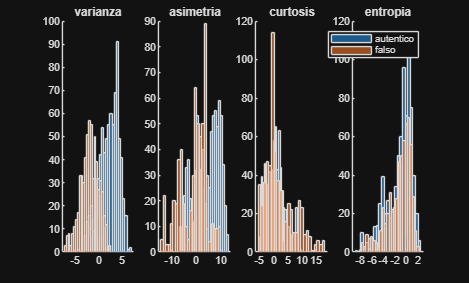

nombres = {'varianza','asimetria','curtosis','entropia'};
figure
for j = 1:4
    subplot(1,4,j); hold on
    histogram(datos(datos(:,5)==0, j), 25)
    histogram(datos(datos(:,5)==1, j), 25)
    title(nombres{j})
end
legend('autentico','falso')

## Se mezcla con semilla fija

rng(2021)
ind = randperm(No_examples);

## Division 60-40, 70-30, 80-20 y 90-10

aqui si hace falta el round: 0.9*1372 = 1234.8

proporciones = [0.6 0.7 0.8 0.9];
for k = 1:4
    n_train = round(proporciones(k) * No_examples);
    S(k).p   = proporciones(k);
    S(k).Xtr = datos(ind(1:n_train), 1:4);
    S(k).ytr = datos(ind(1:n_train), 5);
    S(k).Xte = datos(ind(n_train+1:end), 1:4);
    S(k).yte = datos(ind(n_train+1:end), 5);
end
S

S = 1×4 struct array with fields:
    p
    Xtr
    ytr
    Xte
    yte



save('banknote_splits.mat', 'S')